# Figure 3: S_Ilgn and rI_L6

After Switch!!

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];

S_EEInd = 3; S_IIInd = 2;
S_EE = S_EEtest(S_EEInd);
S_II = S_IItest(S_IIInd);

S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_ElgnInd = 2;
S_Elgn=S_Elgntest(S_ElgnInd);


S_Ilgntest = [1.5 2 2.5]*S_Elgn;%*S_Elgn S_Ilgnhold = [1.5 2 2.5 3];

rE_L6 = 0.25;
rI_L6test  = [1.5 3 4.5 6] * rE_L6;

Panel1 = length(S_Ilgntest); Panel2 = length(rI_L6test);

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

Fig1 = figure('Name','S_Ilgn_rI_L6','units','normalized','outerposition',[0 0 0.8 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .02],[.05 .03],[.08 .10]);


for S_IlgnInd = 1:length(S_Ilgntest)
   
    S_Ilgn = S_Ilgntest(S_IlgnInd);
    
    for rI_L6Ind = 1:length(rI_L6test)
        
        rI_L6 = rI_L6test(rI_L6Ind);
        
        % load data
        CurrentPanelFile = sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end
        
        % First axis for fr
        axes(ha(rI_L6Ind+Panel2*(S_IlgnInd-1)));
        ax1a = gca;

        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        
        % Compute and present the area of extended goodarea
        EtdGoodArea = (CurrentFrE>=2                 & CurrentFrE<=6 & ...
                       CurrentFrI./CurrentFrE    >=3 & CurrentFrI./CurrentFrE    <=4.5);
        EGAratio = sum(double(EtdGoodArea),'all')/(length(CurrentFrE(:)))
        
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrEShow = CurrentFrE;
        CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrEShow(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        
        
        % set ticks, labels, titles, etc.
        if S_IlgnInd == 1
            title(sprintf('r^{IL6}/r^{EL6}=%.1f',rI_L6/rE_L6)) 
        end
        if rI_L6Ind == 1
            ylabel({sprintf('S^{Ilgn}/S^{Elgn}=%.1f',S_Ilgn/S_Elgn),'','S^{EI}/S^{EE}'})
        else
            set(gca,'yticklabel','')
        end
        
        if S_IlgnInd == length(S_Ilgntest)
            xlabel('S^{IE}/S^{II}');
        else
            set(gca,'xticklabel','')
        end
        
        axis square
        axis tight
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        hold on
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
        
        GreyHem = 0.5*ones(size(CurrentFrE));
        if NoFailWeight<0.1 || SIEWeight<1 % if impossible pattern show up on the left...
            FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
            
        end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        
        % Midpoint of Good Area
        GoodArea = (CurrentFrE>=3                 & CurrentFrE<=5 & ...
                    CurrentFrI./CurrentFrE    >=3 & CurrentFrI./CurrentFrE    <=4.25);
        
        GAratio = sum(double(GoodArea),'all')/(length(CurrentFrE(:)))
        if GAratio<0.0135 % skip midpoint if too small
            disp('Good Area too small, Exit.')
        else
            [GA_SEIInd,GA_SIEInd,~] = find(GoodArea);
            MP_SEI = ContourData_7D.S_EItest(floor(mean(GA_SEIInd)))/S_EE;
            MP_SIE = ContourData_7D.S_IEtest(floor(mean(GA_SIEInd)))/S_II;
            scatter(MP_SIE,MP_SEI, 1000, 'k+','LineWidth',2)
        end
        
        
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        axis([min(ContourData_7D.S_IEtest/S_II) max(ContourData_7D.S_IEtest/S_II) ...
              min(ContourData_7D.S_EItest/S_EE) max(ContourData_7D.S_EItest/S_EE)])
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        
        sprintf('id1 = %.1f, id2 = %.1f, Fail = %.2f, SIEWgt = %.2f',...
                S_Ilgn/S_Elgn,rI_L6/rE_L6,NoFailWeight,SIEWeight)
            
        if rI_L6Ind == length(rI_L6test)
            if S_IlgnInd == 1
                Pos1 = get(gca,'Position');
            elseif S_IlgnInd == length(S_Ilgntest)
                Pos2 = get(gca,'Position');
            end
        end
    end
end

EGAratio = 0.1035

GAratio = 0.0339

ans = 'id1 = 1.5, id2 = 1.5, Fail = 0.74, SIEWgt = 1.16'

EGAratio = 0.0800

GAratio = 0.0272

ans = 'id1 = 1.5, id2 = 3.0, Fail = 0.73, SIEWgt = 1.17'

EGAratio = 0.0620

GAratio = 0.0208

ans = 'id1 = 1.5, id2 = 4.5, Fail = 0.71, SIEWgt = 1.16'

EGAratio = 0.0523

GAratio = 0.0170

ans = 'id1 = 1.5, id2 = 6.0, Fail = 0.53, SIEWgt = 1.04'

EGAratio = 0.0681

GAratio = 0.0238

ans = 'id1 = 2.0, id2 = 1.5, Fail = 0.74, SIEWgt = 1.16'

EGAratio = 0.0510

GAratio = 0.0176

ans = 'id1 = 2.0, id2 = 3.0, Fail = 0.69, SIEWgt = 1.14'

EGAratio = 0.0373

GAratio = 0.0145

ans = 'id1 = 2.0, id2 = 4.5, Fail = 0.43, SIEWgt = 1.15'

EGAratio = 0.0013

GAratio = 5.4688e-04

Good Area too small, Exit.


ans = 'id1 = 2.0, id2 = 6.0, Fail = 0.18, SIEWgt = 1.29'

EGAratio = 0.0382

GAratio = 0.0157

ans = 'id1 = 2.5, id2 = 1.5, Fail = 0.48, SIEWgt = 1.27'

EGAratio = 0.0154

GAratio = 0.0044

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 3.0, Fail = 0.27, SIEWgt = 1.37'

EGAratio = 0.0033

GAratio = 0.0013

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 4.5, Fail = 0.11, SIEWgt = 1.51'

EGAratio = 0.0034

GAratio = 6.6406e-04

Good Area too small, Exit.


ans = 'id1 = 2.5, id2 = 6.0, Fail = 0.03, SIEWgt = 1.52'


cbr = colorbar(ax1a, 'Position', [Pos2(1)+Pos2(3)+0.02  Pos2(2)  0.03  Pos1(2)+Pos1(4)-Pos2(2)])

cbr =   ColorBar - 属性:

    Location: 'manual'
      Limits: [-0.1000 15]
    FontSize: 9
    Position: [0.9200 0.0500 0.0300 0.9200]
       Units: 'normalized'

  显示 所有属性


caxis([0 15])
set(cbr,'YTick',0:15)

Save figures

FigurePaperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'Figure3';
savefig(Fig1,[FigurePaperpath FigName1 '.fig']);


Print Figs

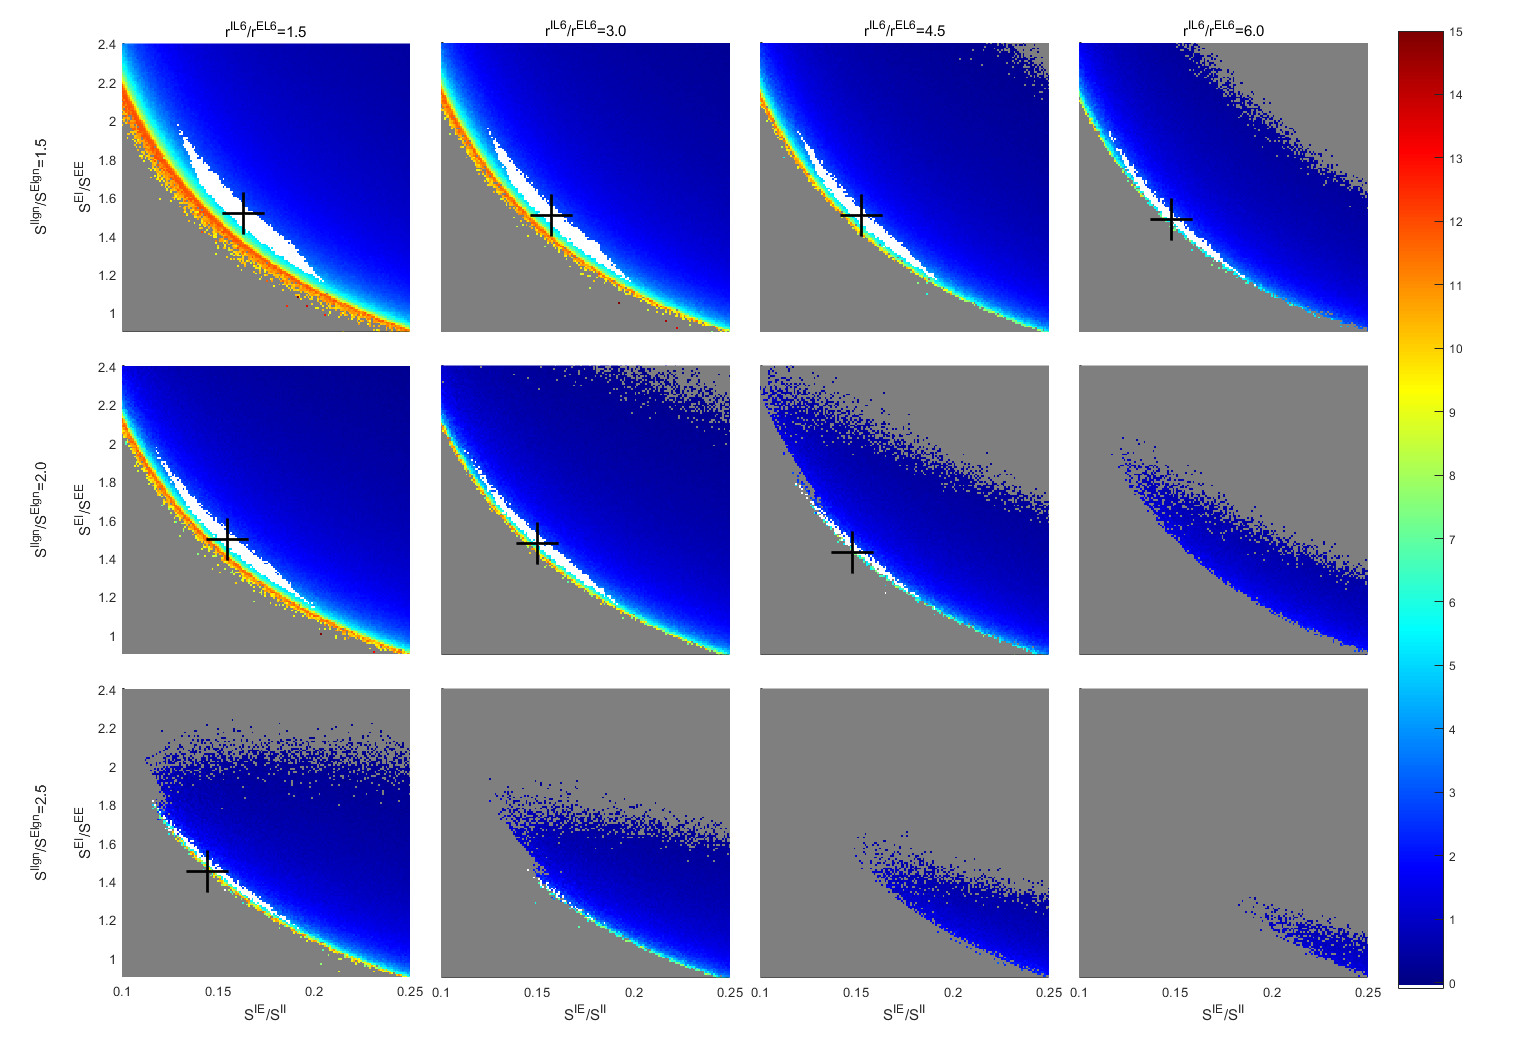

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [36,29];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[FigurePaperpath FigName1 '.pdf'],'Resolution',900)